# Running Grid Code Scenerios in Parallel

Simulation studies can use measured events and simulated data points to test renewable systems prior to integration. In this study, the wind farm is tripped from the grid connection according to the two extremes of IEEE 1547-2018: the must ride through and may ride through. Required reactive power support is investigated.

modelName = 'pmuReplay_multiSim';
eventFiles = 'PMU_Events/*.csv';
selectedEvents = [1, 4, 7, 11];
[T,V,F] = importEventData(eventFiles,selectedEvents);

## PMU Data and Modes to Simulate

Multiple measured datasets can be fed into the simulation, in addition to other simulated conditions, such as wind speed. 

eventVec = [1 2 3 4];
tripVec = [1 2];
windVec = 5:5:20;
[inputVec, numSim] = generateTests(eventVec,windVec,tripVec);

## Setup Simulation Input to leverage Parallel Simulations

The Simulink.SimulationInput class can be used to setup varying inputs/parameters for parallel simulations. We vary the grid event, when the wind farm trip occurs and the wind speed.

for i = 1:numSim
    in(i) = Simulink.SimulationInput(modelName);
    in(i) = in(i).setVariable('eventIdx',inputVec(i,1));
    in(i) = in(i).setVariable('windSpd',inputVec(i,2));
    in(i) = in(i).setVariable('tripMethod',inputVec(i,3));
end
in(1)

ans =   SimulationInput with properties:

          ModelName: 'pmuReplay_multiSim'
       InitialState: [0×0 Simulink.SimState.ModelSimState]
      ExternalInput: []
    ModelParameters: [0×0 Simulink.Simulation.ModelParameter]
    BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
          Variables: [1×3 Simulink.Simulation.Variable]
          PreSimFcn: []
         PostSimFcn: []
         UserString: ''


## Parallel Simulations using "parsim" command

The parsim command distributes the parallel simulations created with the Simulink.SimulationInput class. These simulations can be distributed locally on multiple cores of a processor or even to a distributed computing system.

out = parsim(in, 'ShowSimulationManager', 'on','UseFastRestart',true,'ShowProgress','off');

## View Results

We can plots the reactive power supplied by the wind farm under various grid events and wind conditions to see the different in protection strategies. This same method could be used to evaluate grid code compliance under wide operating conditions or testing wind farm control strategies under various conditions and loads.

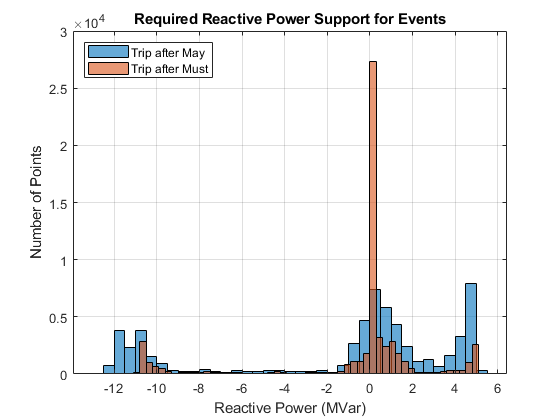

[Qout_must, Qout_may] = extractResults(out);

figure(); histogram(Qout_may);
hold on; grid on;
histogram(Qout_must); hold off;
legend('Trip after May','Trip after Must','Location','northwest');
title('Required Reactive Power Support for Events')
xlabel('Reactive Power (MVar)');
ylabel('Number of Points');

clearvars eventFiles selectedEvents

function [T,V,F] = importEventData(dirLoc,fileIdx)

    filesList = ls(dirLoc);
    i = 1;
    T = cell(1,numel(fileIdx)); V = T; F = T;
    for idx = fileIdx
        dataMeas = readtable(filesList(idx,:)); % read csv file
    
        T{i} = dataMeas.Time;
        V{i} = dataMeas.V;
        F{i} = dataMeas.F;

        i = i + 1;
    end

end

function [inputVec, numSim] = generateTests(a,b,c)
    [xVec,yVec,zVec] = meshgrid(a,b,c);
    inputVec = [xVec(:) yVec(:) zVec(:)];
    numSim = size(inputVec,1);
end

function [Qout_must, Qout_may] = extractResults(out)
    numSim = size(out,2);
    Qout_must = []; Qout_may = [];
    for i = 1:numel(out)
        if i <= numSim/2
            Qout_must = [Qout_must; out(i).yout(:)];
        else
            Qout_may = [Qout_may; out(i).yout(:)];
        end
    end
end